# **IO425 - LVDT/RVDT/Resolver Emulation**

This example shows you how to setup the IO425 I/O module, in order to verify the basic functionality.

The IO425 is a LVDT/RVDT/Resolver emulation I/O module with up to four 4-wire channels. Each channel can be configured to use an internal or external excitation signal.

The Simulink model features the [IO425 - Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io425_setup) and [IO425 - Write](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io425_write) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO425 module installed       

- Connector cable from the I/O module to the terminal board

- Terminal board

- Oscilloscope

### Test Setup

Channel 1: LVDT

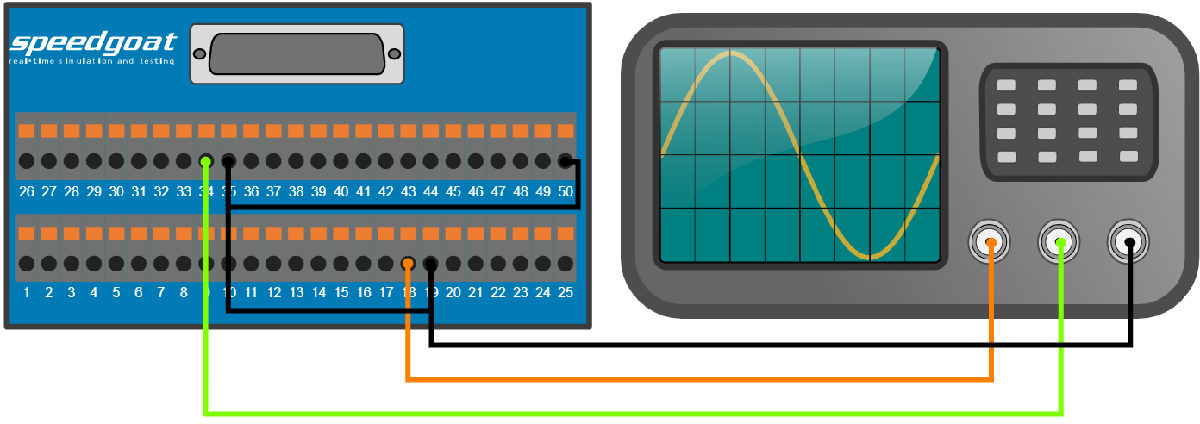

Channel 3: Resolver

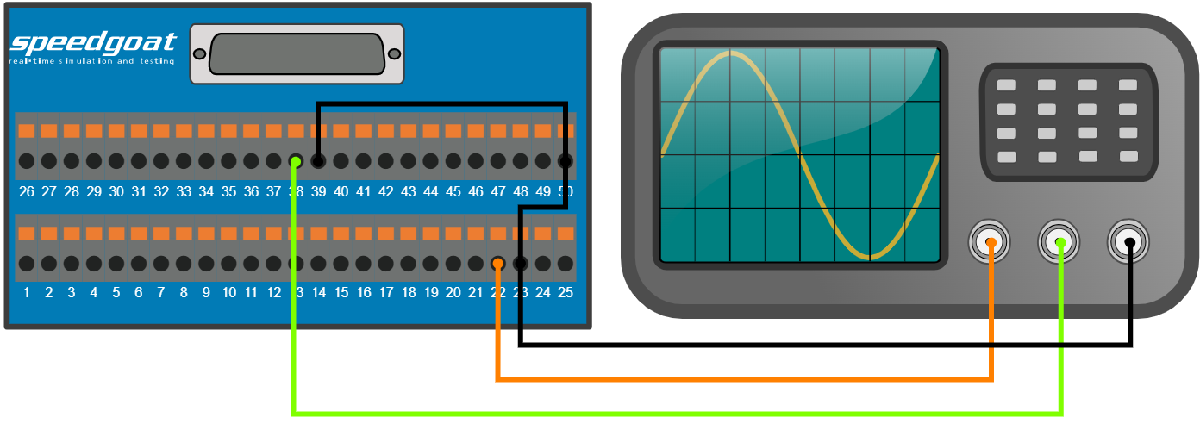

In this example, channel 1 is configured as a 4-wire LVDT Sensor and channel 3 as a Resolver. On the terminal board of the I/O module, connect an oscilloscope to the respective A and B outputs as shown above. Refer to the [IO425 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io425_pin_mapping).

## Open the Simulink Model

 
% Open Simulink model
modelName = 'sgMdl_IO425_LVDTResolverEmulation';
open_system(modelName);

### Model Description

In the model, a sine wave signal is applied on channel 1, which is configured as a 4-wire LVDT sensor. The signal emulates a movement of the LVDT core from the minimum to the maximum value possible (-100 % to 100 %). A null offset voltage of 50 mV is configured in order to detect very small changes at the extreme levels.

Channel 3 is configured as a resolver sensor, which emulates the constant core rotation speed of the applied sawtooth signal. Both channels use the internal excitation signal for simplicity. An external signal could also be connected if preferred.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode',   'external')   % put model into External Mode
set_param(modelName,'SimulationCommand','connect')    % connect with External Mode

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check whether the channel configured as a 4-wire LVDT is working as expected, connect the oscilloscope to channel 1 as shown above. After the model has been downloaded, the initial values are applied, and the core position is set to zero displacement where both outputs have the same amplitude as shown below.

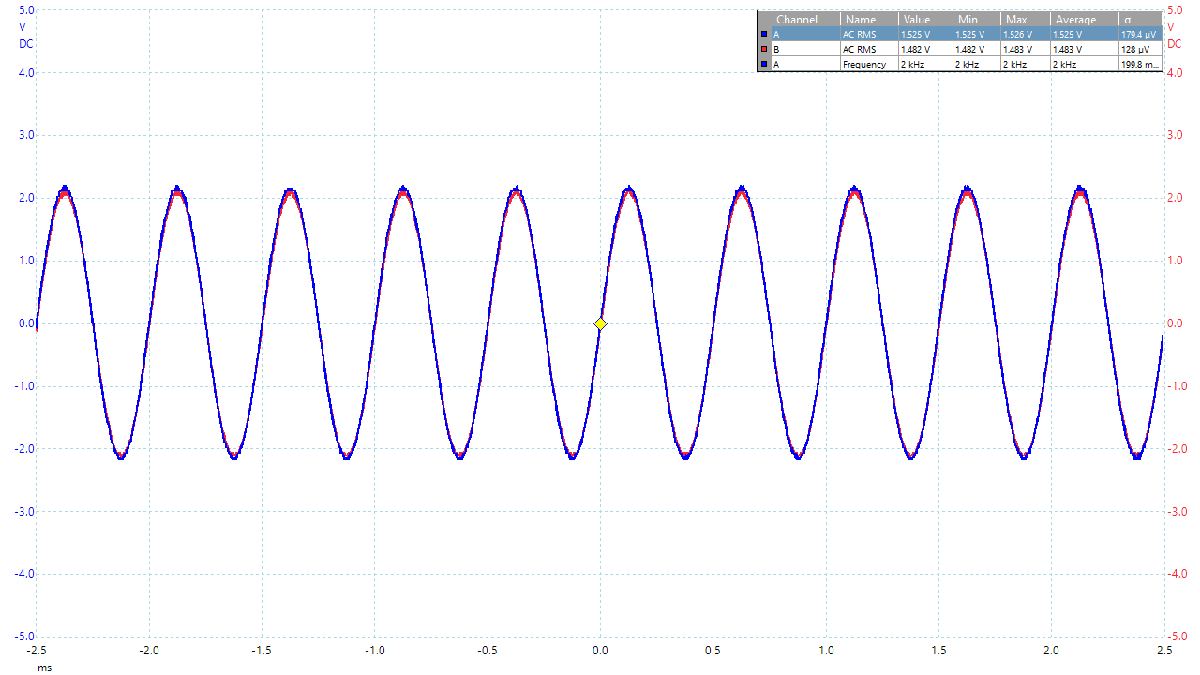

After starting the model, the outputs will alternately reach their maximum and minimum values as the LVDT core is moving. At the minimal value, the measured RMS-voltage must correspond to the configured **Null Offset**.

Connect the oscilloscope to channel 3 for the resolver sensor emulation as shown above. The initial value is set to 45°, otherwise output A (sine output) would be zero volts after downloading the application.

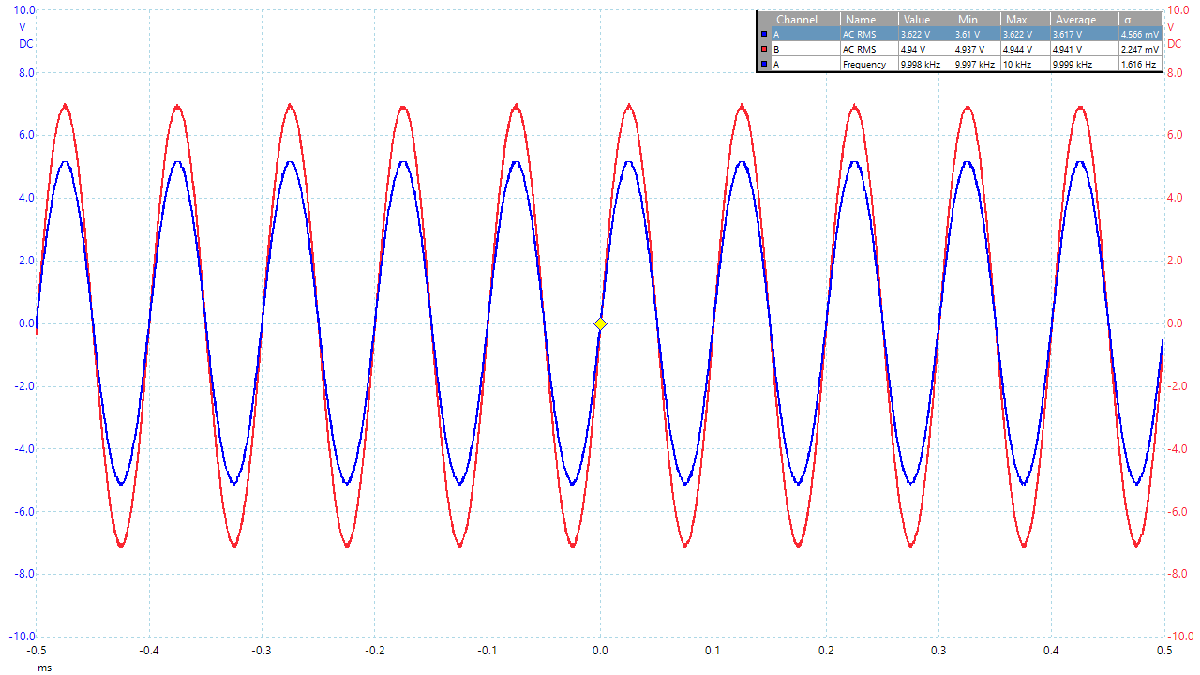

The core will rotate at a constant speed when the application is running. The outputs will therefore change their amplitude and phase accordingly. 

## Additional References

- [IO425 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io425)